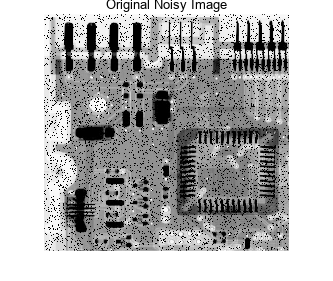

clear; clc;

% circuitboard-a.tif
noise_a = imread('images/circuitboard-a.tif');
figure();
imshow(noise_a);
title('Original Noisy Image');

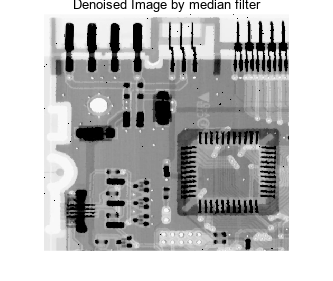

% we use mediean filter
[median_a, median_threshold_a] = my_median_filter(noise_a, zeros(3));
figure();
imshow(median_a);
title('Denoised Image by median filter');

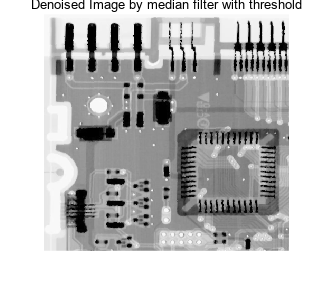

figure();
imshow(median_threshold_a);
title('Denoised Image by median filter with threshold');

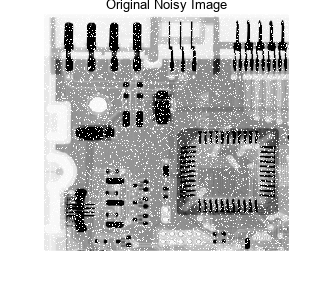


% circuitboard-b.tif
noise_b = imread('images/circuitboard-b.tif');
figure();
imshow(noise_b);
title('Original Noisy Image');

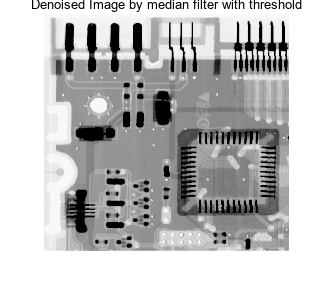


% we use biased median filter
[median_threshold_b] = my_median_filter2(noise_b, zeros(3));
figure();
imshow(median_threshold_b);
title('Denoised Image by median filter with threshold');

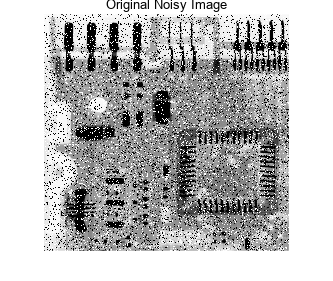


% circuitboard-c.tif
noise_c = imread('images/circuitboard-c.tif');
figure();
imshow(noise_c);
title('Original Noisy Image');

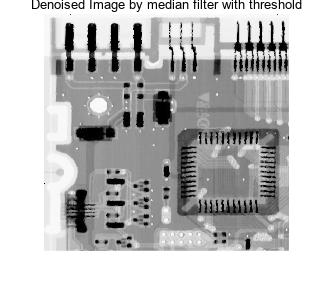


% we use biased median filter
[median_threshold_c] = my_median_filter3(noise_c, zeros(3));
figure();
imshow(median_threshold_c);
title('Denoised Image by median filter with threshold');

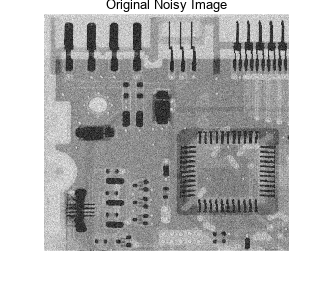


% circuitboard-d.tif
noise_d = imread('images/circuitboard-d.tif');
figure();
imshow(noise_d);
title('Original Noisy Image');

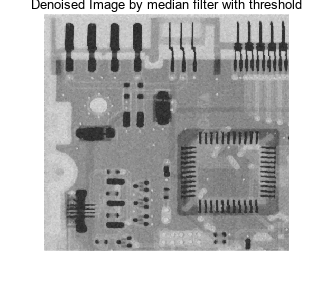


% we use biased median filter
[median_threshold_d] = my_median_filter4(noise_d, zeros(3));
figure();
imshow(median_threshold_d);
title('Denoised Image by median filter with threshold');

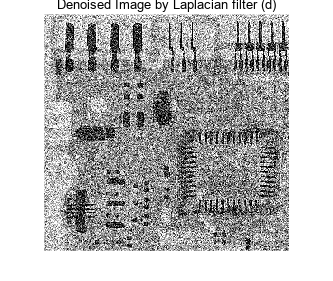


% Laplacian filter
Laplacian_filter = [0 -1 0;
                    -1 5 -1;
                    0 -1 0];
[sharpening_image, ~] = my_conv(noise_d, Laplacian_filter);
figure();
imshow(sharpening_image);
title('Denoised Image by Laplacian filter (d)');

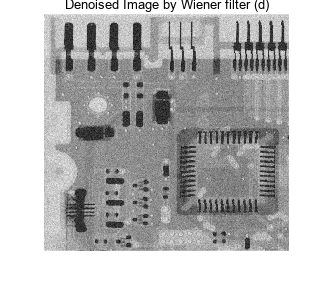


% Wiener Filter 
wiener_filtered = wiener2(noise_d, [3,3], 0.0001);
figure();
imshow(wiener_filtered);
title('Denoised Image by Wiener filter (d)')


% lowpass filter 
d=5

d = 5

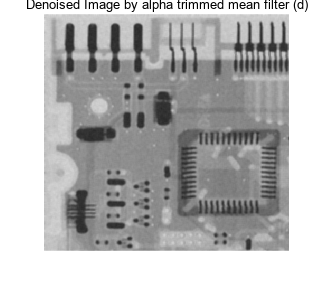

n=5;
lowpass_filtered = my_lowpass_filter(noise_d, ones(n, n), d);
figure();
imshow(lowpass_filtered);
title('Denoised Image by alpha trimmed mean filter (d)');

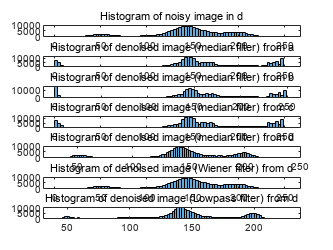


num_images = 7;
figure();
subplot(num_images,1,1);
histogram(noise_d);
title('Histogram of noisy image in d');
subplot(num_images,1,2);
histogram(median_threshold_a);
title('Histogram of denoised image (median filter) from a');
subplot(num_images,1,3);
histogram(median_threshold_b);
title('Histogram of denoised image (median filter) from b');
subplot(num_images,1,4);
histogram(median_threshold_c);
title('Histogram of denoised image (median filter) from c');
subplot(num_images,1,5);
histogram(median_threshold_d);
title('Histogram of denoised image (median filter) from d');
subplot(num_images,1,6);
histogram(wiener_filtered);
title('Histogram of denoised image (Wiener filter) from d');
subplot(num_images,1,7);
histogram(lowpass_filtered);
title('Histogram of denoised image (Lowpass filter) from d');

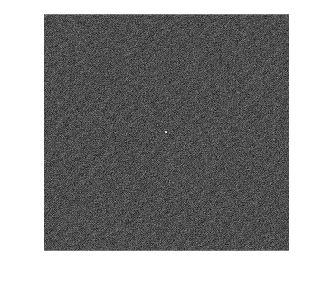


A = double(median_threshold_c);
B = double(noise_d);
noise_var = 0.0001; % 假设噪声方差为0.0001
estimated_nsr = noise_var / var(double(A(:))); % 估计信噪比
H = deconvwnr(B, A, estimated_nsr); % 反卷积得到滤波器H
figure();
imshow(H, []);

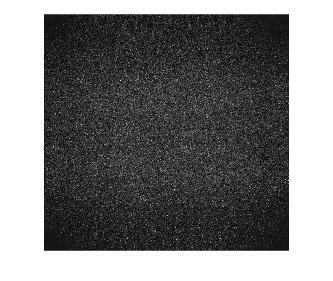

H_fft = fft2(H); % 将滤波器H转换到频域
H_fft_abs = abs(H_fft); % 取频域幅值
H_fft_abs_log = log(H_fft_abs + 1); % 取对数，方便可视化
figure();
imshow(H_fft_abs_log, []); % 可视化滤波器H的频域幅值

function [full_result, crop_result] = my_conv(M, K)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, 'replicate');
M_pad = double(M_pad);
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,2)-1);
        for m = 1:size(K, 1)
            for n = 1:size(K, 2)
                result(i,j)=result(i,j)+M_crop(m,n)*K(size(K,1)-m+1, size(K,2)-n+1);
            end
        end
    end
end
result = uint8(result);
full_result = result(:, :);
x1=1+floor(size(K,1)/2);x2=size(M,1)-floor(size(K,1)/2);
y1=1+floor(size(K,2)/2);y2=size(M,2)-floor(size(K,2)/2);
crop_result = result(x1:x2, y1:y2);
end

function [median1, median_threshold1] = my_median_filter(M, K)
result = zeros(size(M));
result2 = zeros(size(M));
M_pad = padarray(M, size(K)-1, "replicate");
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,1)-1);
        result(i,j)= median(M_crop(:));
        result2(i,j)=median(M_crop(M_crop>0));
    end
end
result = uint8(result);
result2 = uint8(result2);
median1 = result;
median_threshold1 = result2;
end

function [median_threshold1] = my_median_filter2(M, K)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, "replicate");
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,1)-1);
        result(i,j)=median(M_crop(M_crop<255));
    end
end
result = uint8(result);
median_threshold1 = result;
end

function [median_threshold1] = my_median_filter3(M, K)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, "replicate");
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,1)-1);
        result(i,j)=median(M_crop(and(M_crop<255,M_crop>0)));
    end
end
result = uint8(result);
median_threshold1 = result;
end

function [median_threshold1] = my_median_filter4(M, K)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, "replicate");
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,1)-1);
        result(i,j)=median(M_crop(:));
    end
end
result = uint8(result);
median_threshold1 = result;
end

function [lowpass] = my_lowpass_filter(M, K, d)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, 'replicate');
M_pad = double(M_pad);
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,2)-1);
        M_crop = sort(M_crop(:));
        cropped_M_pad = M_crop(floor(d/2)+1:size(M_crop, 1)-ceil(d/2));
        result(i, j) = sum(cropped_M_pad) / size(cropped_M_pad, 1);
    end
end
result = uint8(result);
lowpass = result(:, :);
end

